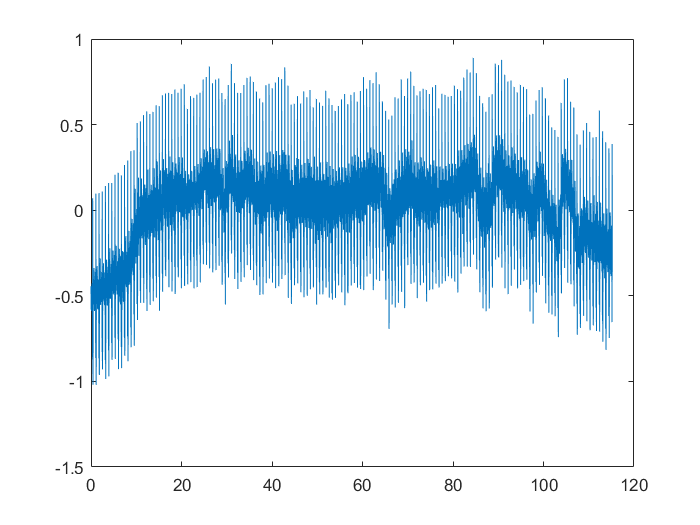

% Preprocessing ECG signal
% Sina Dabiri, 2021
clear

[sig, Fs, tm] = rdsamp('ptbdb/patient001/s0014lre', 1);
data = sig';
plot(tm, sig);

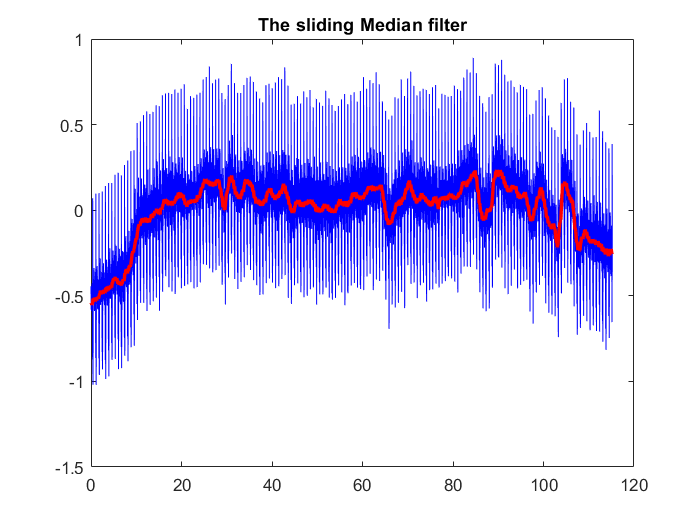

hold on
plot(tm, sig, 'b-');
% 'md' with wlen=0.2 sec
wlen = round(0.6*Fs);
b_md = BaseLine1(data, wlen,'md');

plot(tm, b_md, 'r-', 'LineWidth',2);
title("The sliding Median filter");
hold off

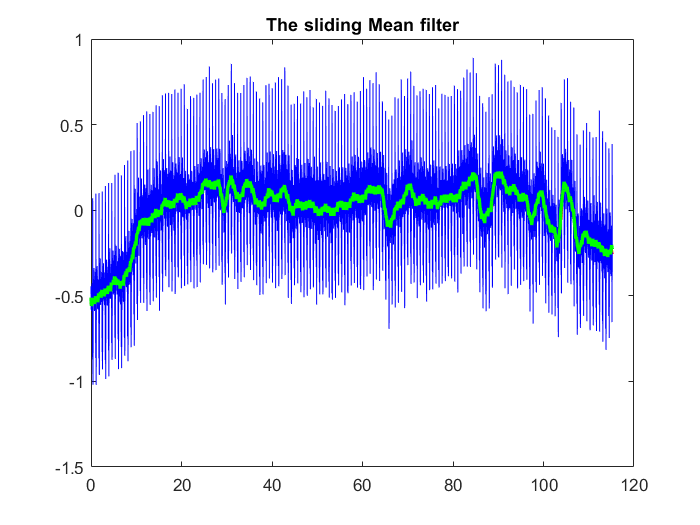

hold on
plot(tm, sig, 'b-');
% 'ma' with wlen=0.3 sec
wlen = round(0.8*Fs);
b_mn = BaseLine1(data, wlen,'mn');

plot(tm, b_mn, 'g-', 'LineWidth',2);
title("The sliding Mean filter");
hold off

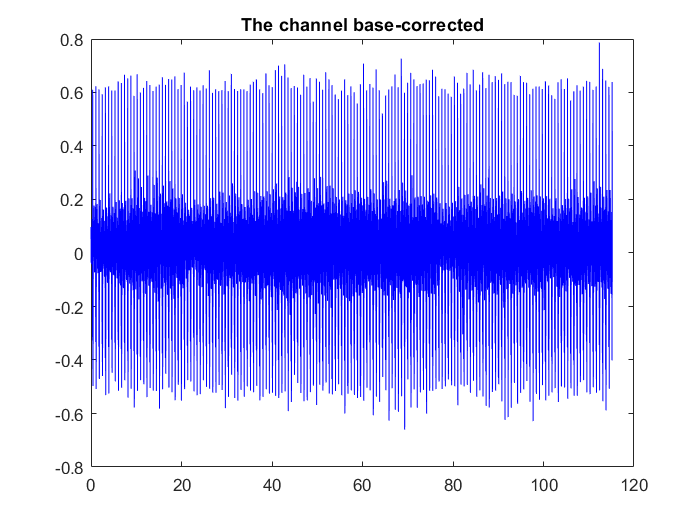

% Powerline noise cancellation

data_base_cor = data - b_md;
plot(tm, data_base_cor, 'b-');
title("The channel base-corrected");

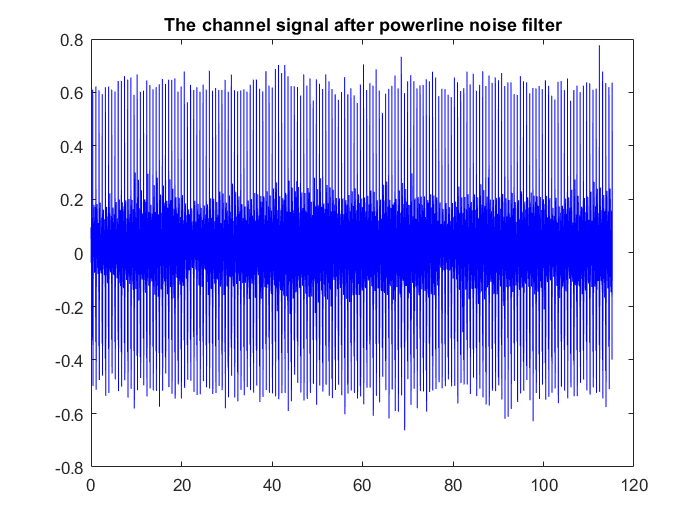

% notch filter design

fs = Fs; % sampling frequency (Hz)
f0 = 60; % powerline frequency (50Hz or 60Hz, depending on the country that the data has been recorded in)
Q = 40; % Q-factor (quality factor) of the notch filter. a parameter that controls the notch quality and is a compromise between transient response time and notch quality
Wo = f0/(fs/2); % powerline frequency normalized by the Nyquist frequency 
BW = Wo/Q; % normalized notch filter bandwidth
[b,a] = iirnotch(Wo,BW); % design the filter numerator and denominator
 
% looking at the frequency response
% fvtool(b, a)
x=  data_base_cor;
% filtering a 1-D signal x (apply it on each channel if the signal is multi-dimensional)
y = filter(b, a, x);
plot(tm, y, 'b-')
title("The channel signal after powerline noise filter");